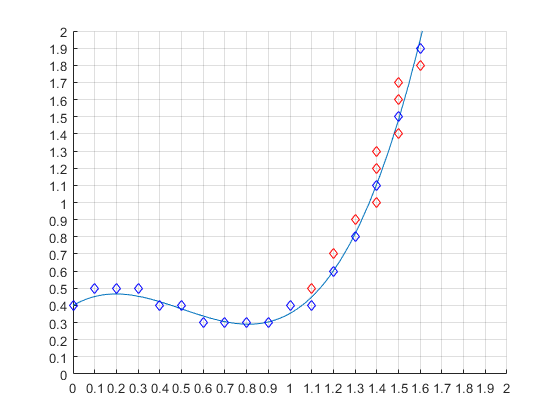

clear
clc
N = 10;
grid_max = 2;
x_grid = 0:1/N:grid_max;
y_grid = 0:1/N:grid_max;
figure();
grid on
xticks(x_grid)
yticks(y_grid)
xlim([x_grid(1),x_grid(end)])
ylim([y_grid(1),y_grid(end)])

syms x_sym
hold on
fplot(func(x_sym))
clear x_sym

j = 1;
for i = 1:length(x_grid) - 1
    counter = 0;
    y = func(x_grid(i));
    if (y > grid_max)
        break;
    end
    if func(x_grid(i + 1)) > func(x_grid(i))
        while abs(y_grid(j+1) - y) < abs(y - y_grid(j))
            j = j + 1;
            counter = counter + 1;
            if (j + 1 > length(y_grid))
                break;
            end
        end
        if (counter > 1) && (i > 1)
            for k = 1:floor(counter/2)
                scatter(x_grid(i-1),y_grid(j - counter + k),'rd')
            end
            for k = floor(counter/2) - 1:counter - k - 1
                scatter(x_grid(i),y_grid(j - k),'rd')
            end
        end
    else
        while abs(y_grid(j-1) - y) < abs(y - y_grid(j))
            j = j - 1;
            counter = counter + 1;
            if (j + 1 > length(y_grid))
                break;
            end
        end
        if (counter > 1) && (i > 1)
            for k = 1:floor(counter/2)
                scatter(x_grid(i-1),y_grid(j - counter + k),'rd')
            end
            for k = floor(counter/2) - 1:counter - k - 1
                scatter(x_grid(i),y_grid(j - k),'rd')
            end
        end
    end
    scatter(x_grid(i),y_grid(j),'bd');
end
hold off

function [y] = func(x)
y = 0.3 + 1.55 * (x+0.4)^3 - 4.2*x^2;
% y = 0.1 + 3 * x^2;
end